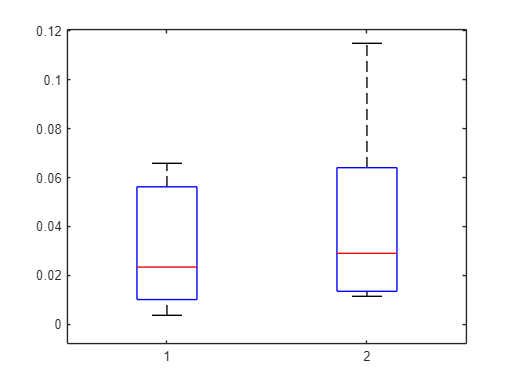

rootdir = "";
folders = ["M119"+filesep "M120"+filesep "M292"+filesep "M319"+filesep ...
    "M231"+filesep "M314"+filesep "M316"+filesep "M318"+filesep "M210"+filesep];
cohort = ["D1","D1","D1","D1","G1","G1","G1","G1","D1"];
sessions = ["early", "trained", "grouping"];

rate_context_mean = nan(length(folders),3,2);
rate_context_std = nan(length(folders),3,2);

s_max = length(sessions);
ablate_percent = 0.50;

for f = 1:length(folders)
    for s = 1:s_max
        try
            A=load(folders(f)+"binned_activity_decode_"+sessions(s)+".mat");    
            ds = 10; % how many samples to downsample

            N_cells = size(A.a_use,2);
            N_cells_use = round(ablate_percent*N_cells);
            
            % keep the 1-ablate_percent most unstable cells
            [corr_temp,idx_cells_use] = topkrows(A.corr_coef,N_cells_use,'ascend');
            
            A_use = A.a_use(1:ds:end,idx_cells_use);
            context_use_sub = A.context_use(1:ds:end);

            rate_context_mean(f,s,1) = nanmean(A_use(context_use_sub==1),1);
            rate_context_mean(f,s,2) = nanmean(A_use(context_use_sub==2),1);

            rate_context_std(f,s,1) = nanstd(A_use(context_use_sub==1),0,1);
            rate_context_std(f,s,2) = nanstd(A_use(context_use_sub==2),0,1);

        catch
        end

    end
end
boxplot([rate_context_mean(:,3,1);rate_context_mean(:,3,2)],[ones(size(rate_context_mean(:,3,1)));2*ones(size(rate_context_mean(:,3,1)))])

ttest(rate_context_mean(:,3,1),rate_context_mean(:,3,2))

ans = 0